This script follows the steps required to run a model with inputs chosen by the reader, along with the associated functions developed in MATLAB. Workflow requires functions from tribem (Delano et al., 2017; Loveless, 2019; Thomas, 1993), Structural Geology Algorithms (Allmendinger et al., 2011), and Blocks (Meade and Loveless, 2009). Program uses slightly different sign conventions than tribemx, requiring that line 52 of ProjectStrainPartialsMats.m be modified to Gp(2:3:end, :) = ud;. 

# Create Fault Map

To run this function, you must input the filename of a fault mesh (can be generated from ArcMap) and a spherical mesh (created using gmshfaults). Alternatively, accept the standard fault map and hotspot input used in the project. Adjustment necessary to gmshfaults_Windows to run on Mac or Linux  platforms. 

load data.mat
newFaultMap=0;
if newFaultMap==1
    filename="";
    path="";
    [faults, faultsHotspot] = meshFaults(filename, hotspot, dips, path);
end
%numberedFaults(faults)

# Run Comparison

To run this function, you must choose a hotspot contribution (mm/year), an azimuth of rifting (0-180°), whether to allow fault opening ('All', 'None', or listed fault numbers formatted as 1,2,3), and the desired comparison dataset. Function requires comparison datasets contained in comparison.mat (slipData, stressData, eqData, eqDataStress, and GPSData). Function outputs rakes for each triangular dislocation element on each fault, comparison axes, and the angular misfit with the comparison dataset for each comparison data point. 

load comparison.mat
hotspotContribution=0;
azimuth=125;
faultOpening="None";
comparison=3;
[rakes, results, anglesbetween, misfit] = runComparison(faults, faultsHotspot, hotspotContribution, azimuth-90, faultOpening, comparison, slipData, stressData, eqData, eqDataStress, GPSData);

# View Results

View output rakes on each element of the fault mesh, the resulting comparison axes, and the overall misfit with the comparison dataset. 

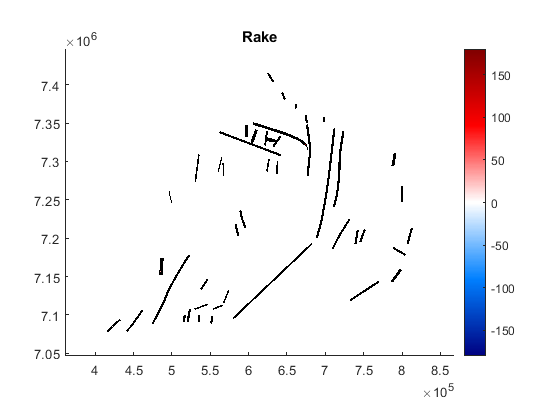

meshview(faults.c, faults.v, rakes(1:sum(faults.nEl), 1));
title('Rake')
colorbar
caxis ([-180 180])
colormap bluewhitered

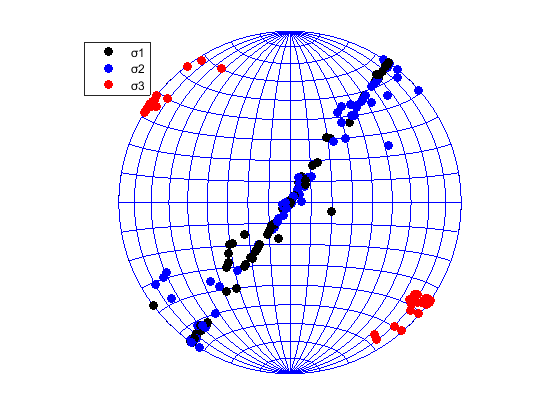


makeStereonet(results, comparison);


sprintf(strcat("Misfit: ", num2str(misfit)))

ans = "Misfit: 38.2804"